# Correlation integral dependence on aromatic, sidechain, and backbone parameters

Plot average and standard deviation of correlation integral for all different sets of parameters.

## Read in Data

fileLocation = '/home/rachael/cluster/scratch/ramansbach/coarsegraining/hoomd/patchy/analyze/';
AAnames = {'0','37','185','370','740'};
SCnames = {'0','02','2','4','10'};
BBnames = {'0','001','06','1','4'};
%track different types of parameters/clustering types
colors = {};
c1 = [0 0.4470 0.7410];
c2 = [0.8500 0.3250 0.0980];
c3 = [0.9290 0.6940 0.1250];
c4 = [0.4940 0.1840 0.5560];
c5 = [0.4660 0.6740 0.1880];
c6 =  [0.3010 0.7450 0.9330];
c7 = [0.6350 0.0780 0.1840];
%clusters where nothing is 0
for aa = 1:length(AAnames)
    for sc = 1:length(SCnames)
        for bb = 1:length(BBnames)
            colors{aa}{sc}{bb} = c1;
        end
    end
end
for aa = 1:length(AAnames)
    for sc = 1:length(SCnames)
        for bb = 1:length(BBnames)
            if aa == 1
                if sc == 1
                    colors{aa}{sc}{bb} = c5;
                elseif bb == 1
                    colors{aa}{sc}{bb} = c7; 
                else
                    colors{aa}{sc}{bb} = c2;
                end
            else
                if sc == 1
                   if bb == 1
                       colors{aa}{sc}{bb} = c6;
                   else
                       colors{aa}{sc}{bb} = c3;
                   end
                else
                    if bb == 1
                       colors{aa}{sc}{bb} = c4; 
                    end
                end
            end
        end
    end
end

%these do not form clusters (average mu2 < 2 for contact)
colors{1}{2}{1} = 'k';
colors{1}{3}{1} = 'k';
colors{2}{1}{1} = 'k';
colors{2}{2}{1} = 'k';
colors{4}{1}{1} = 'k';


fbase = 'mols10000_';
paramMatrix = zeros(length(AAnames),3);
contactMatrix = zeros(length(AAnames),7);
opticalMatrix = zeros(length(AAnames),7);
alignedMatrix = zeros(length(AAnames),7);
dataCell = {};
for i = 1:length(AAnames)
    for sc = 1:length(SCnames)
        for bb = 1:length(BBnames)
    foldname = [fileLocation AAnames{i} '-' SCnames{sc} '-' BBnames{bb} '/'];
    
    fname = [foldname fbase AAnames{i} '-' SCnames{sc} '-' BBnames{bb} '_run-corrcalc.dat'];
    
        
    try
       dataMatrix = importdata(fname);
    catch
       dataMatrix = []; 
    end
    dataCell{i}{sc}{bb} = dataMatrix;
        end
    end
end

Okay two things:

First, there's an obvious region break according to the variance, and we can do a local min search where we fit three lines to the variance to pick the exact breaks.

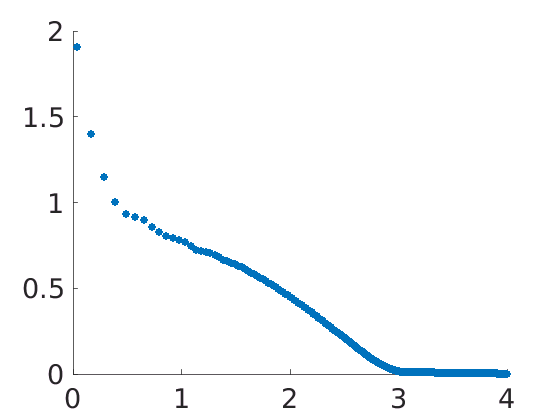

xsig = log(x(~isnan(std(log(yMeans),0,2))));
sigma = std(log(yMeans),0,2);
sigma = sigma(~isnan(sigma));
imax = find(abs(xsig-4)==min(abs(xsig-4)));
xsig = xsig(1:imax);
sigma = sigma(1:imax);
figure()
hold on
plot(xsig,sigma,'.','markersize',20)
set(gca,'fontsize',20)

checkNo = 10; %check 10 points to either side
iguess1 = find(abs(xsig-0.4806)==min(abs(xsig-0.4806)));
iguess2 = find(abs(xsig-3)==min(abs(xsig-3)));
lf = fittype('a*x+b','independent','x');
minerr = Inf;
warning('off','curvefit:fit:noStartPoint')

for i1 = max(iguess1-checkNo,2):min(iguess1+checkNo,length(sigma)-2)
    for i2 = max(iguess2-checkNo,2):min(iguess2+checkNo,length(sigma)-2)
       [P1,gP1] = fit(xsig(1:i1),sigma(1:i1),lf);
       [P2,gP2] = fit(xsig(i1:i2),sigma(i1:i2),lf);  
       [P3,gP3] = fit(xsig(i2:end),sigma(i2:end),lf);
       %compute total RMSE
       %RMSET = ((j-1)/(length(vals)-1))*RMSE1 + ((length(vals)-j)/(length(vals)-1))*RMSE2,
        RMSET = ((i1-1)/(length(sigma)-1))*gP1.rmse + ((i2-i1)/(length(sigma)-1))*gP2.rmse + ((length(sigma)-i2)/(length(sigma)-1))*gP3.rmse;
        if RMSET < minerr
           minerr = RMSET;
           split1 = i1;
           split2 = i2;
        end
    end
end

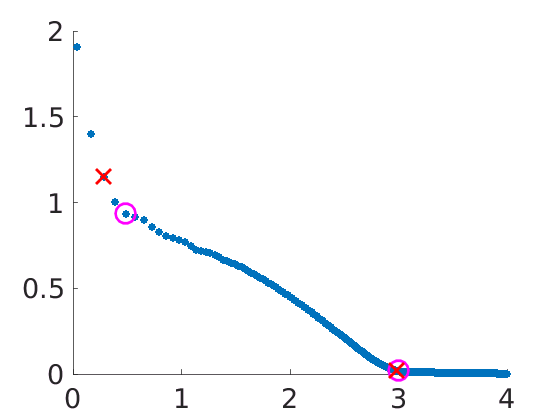

plot([xsig(iguess1) xsig(iguess2)],[sigma(iguess1) sigma(iguess2)],'mo','linewidth',2,'markersize',15)
plot([xsig(split1) xsig(split2)],[sigma(split1) sigma(split2)],'rx','markersize',15,'linewidth',2)

x1 = xsig(split1)

x1 = 0.2799

x2 = xsig(split2)

x2 = 2.9805

Check a linear fit for the collapsed region.

## Plot Data

For each non empty piece of data, get the mean and the standard deviation and plot it on the figure.

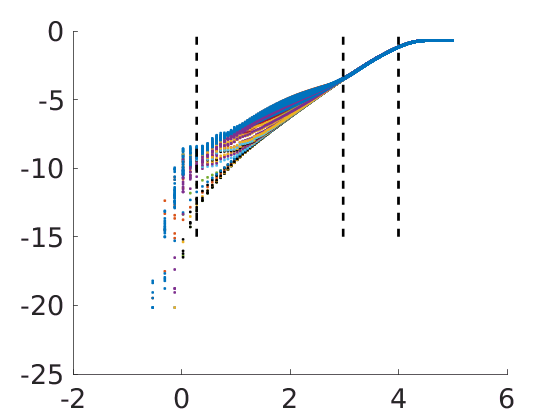

figure()
set(gca,'fontsize',20)
hold on;
yMeans = [];
yind = 1;

for a = 1:length(AAnames)
    for sc = 1:length(SCnames)
        for bb = 1:length(BBnames)
            dataMatrix = dataCell{a}{sc}{bb};
            if ~isempty(dataMatrix)
                x = dataMatrix(:,1);
                y = mean(dataMatrix(:,2:end),2);
                yMeans(:,yind) = y;
                
                yind = yind + 1;
                s = std(dataMatrix(:,2:end),0,2);
                %errorbar(x,y,s,'linewidth',2)
                plot(log(x),log(y),'.','color',colors{a}{sc}{bb},'linewidth',1.5)
                %xlim([log(1.5) log(73.3)])
                %xlim([0 4.5])
                
                %ylim([-15 0])
            end
        end
    end
end
plot(4*ones(size(-15:0)),-15:0,'--k','linewidth',2)
plot(x2*ones(size(-15:0)),-15:0,'--k','linewidth',2)
plot(x1*ones(size(-15:0)),-15:0,'--k','linewidth',2)

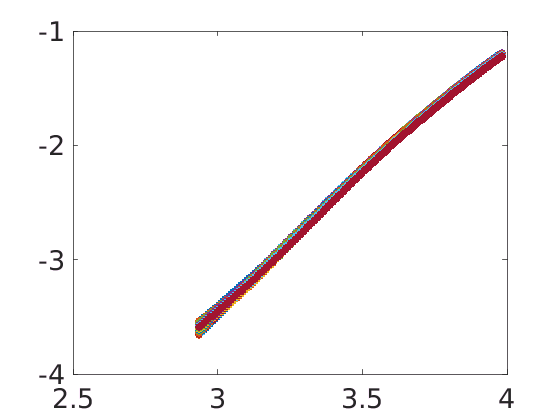


figure()
lf = fittype('a*x+b','independent','x');
plot(log(x(split2:imax)),log(yMeans(split2:imax,:)),'.','markersize',20)
set(gca,'fontsize',20)

[P1,gP1] = fit(log(x(split2:imax)),mean(log(yMeans(split2:imax,:)),2),lf);

Second, it's unclear as to whether a single linear fit or two is better for that central region, so use AIC to determine that for each run.

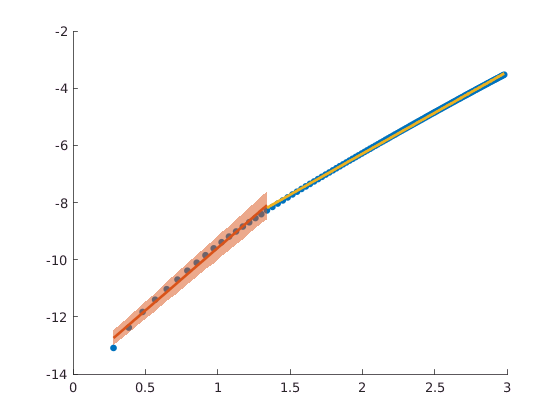

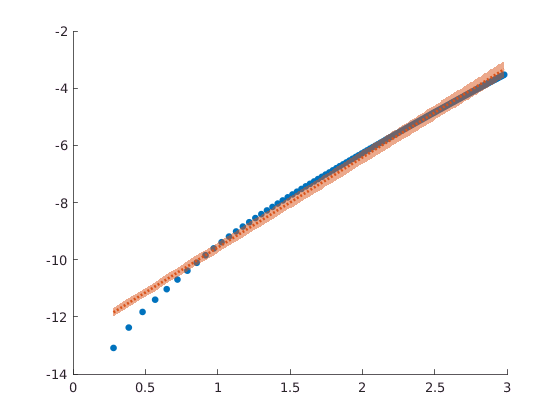

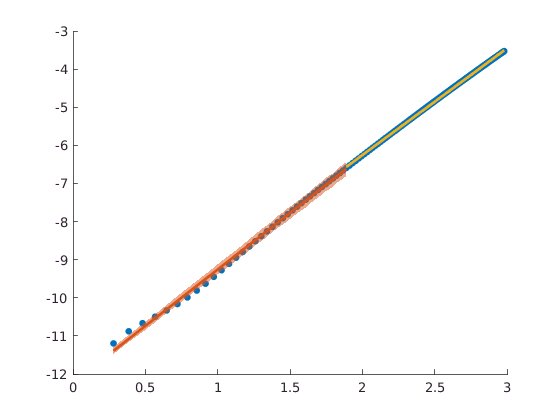

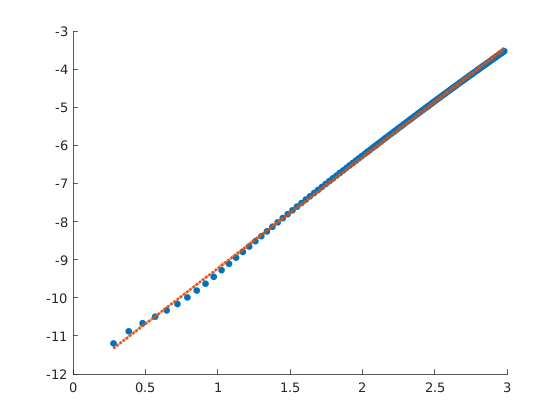

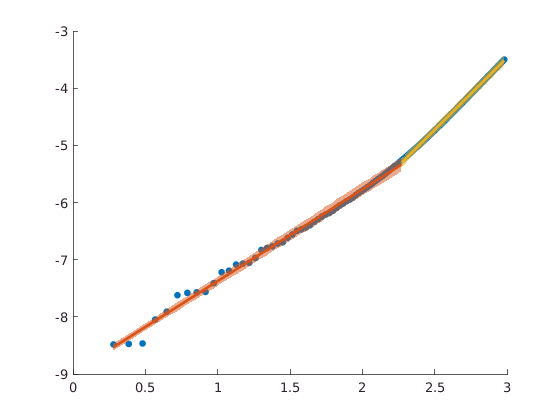

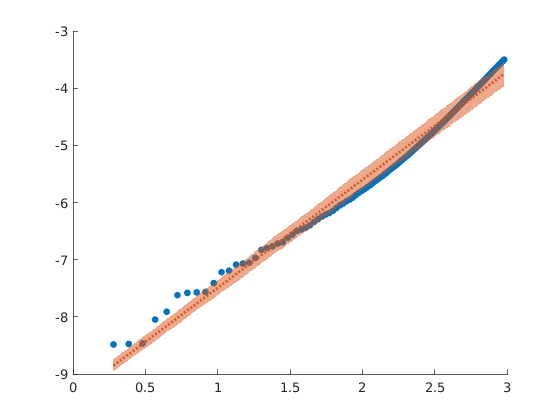

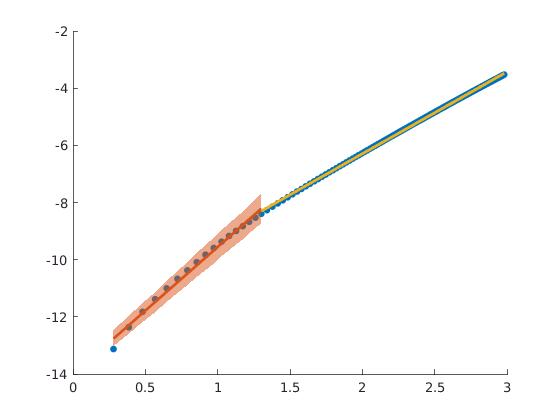

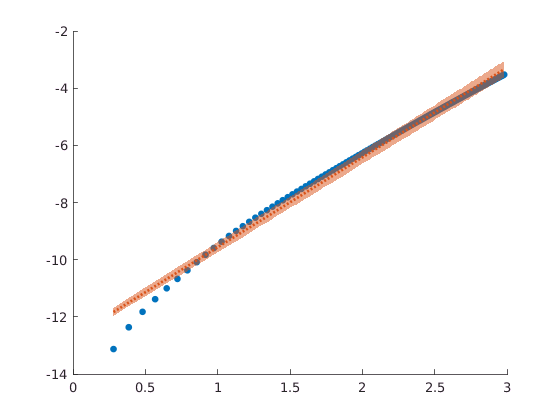

addpath('/home/rachael/Analysis_and_run_code/stats_analysis/');
figure()
dims = [];
for a = 1:length(AAnames)
    for sc = 1:length(SCnames)
        for bb = 1:length(BBnames)
            dataMatrix = dataCell{a}{sc}{bb};
            if ~isempty(dataMatrix)
                x = log(dataMatrix(:,1));
                y = log(mean(dataMatrix(:,2:end),2));
                
                s = std(dataMatrix(:,2:end),0,2);
                imin = find(abs(x-x1)==min(abs(x-x1)));
                imax = find(abs(x-x2)==min(abs(x-x2)));
                [l1,l2,splt,lsing,aic1,aic2] = Lmethod(x(imin:imax),y(imin:imax),[],0,0);
                AA = str2double(AAnames{a})/100;
                if strcmp(SCnames{sc},'02')
                   SC = 0.2; 
                else
                   SC = str2double(SCnames{sc}); 
                end
                if strcmp(BBnames{bb},'001')
                    BB = 0.01;
                else
                    BB = str2double(BBnames{bb});
                end
                if aic1 < aic2
                   d1 = lsing.a;
                   d2 = lsing.a;
                   xsplit = 0;
                else
                    d1 = l1.a;
                    d2 = l2.a;
                    xsplit = x(splt);
                end
                dimvec = [AA SC BB d1 d2 xsplit];
                dims = [dims;dimvec];
            end
        end
    end
end

## Now let's investigate these dimensions as a function of our parameter space

**Region 1**

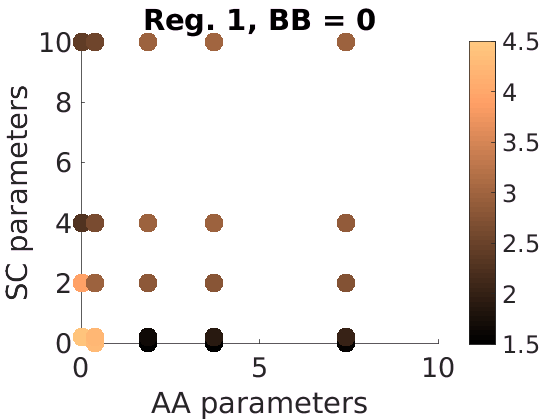

saveloc = '/home/rachael/Dropbox/Images/Presentations/Research-11-8-17';
figure()
hold on
colormap copper
i02 = find((dims(:,3)==0) & (dims(:,6) ~=0));
i01 = find((dims(:,3)==0) & (dims(:,6) ==0));
scatter(dims(i01,1),dims(i01,2),200,dims(i01,4))
scatter(dims(i02,1),dims(i02,2),200,dims(i02,4),'filled')
colorbar
caxis([1.5 4.5])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Reg. 1, BB = 0')

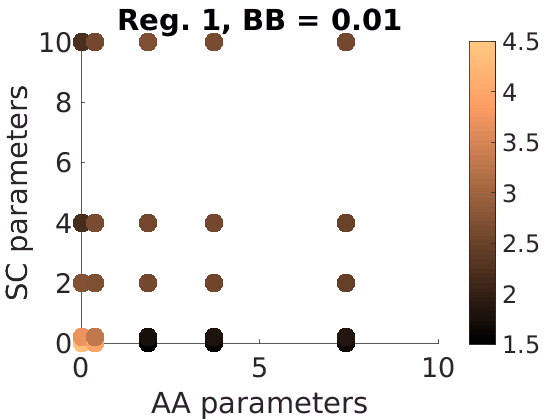

savefig([saveloc '/dimr1bb0'])
saveas(gcf,[saveloc '/dimr1bb0'],'pdf')

figure()
hold on
colormap copper
i02 = find((dims(:,3)==0.01) & (dims(:,6) ~=0));
i01 = find((dims(:,3)==0.01) & (dims(:,6) ==0));
scatter(dims(i01,1),dims(i01,2),200,dims(i01,4))
scatter(dims(i02,1),dims(i02,2),200,dims(i02,4),'filled')
colorbar
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Reg. 1, BB = 0.01')
caxis([1.5 4.5])

savefig([saveloc '/dimr1bb01'])
saveas(gcf,[saveloc '/dimr1bb01'],'pdf')

figure()
hold on
colormap copper
i02 = find((dims(:,3)==6) & (dims(:,6) ~=0));
i01 = find((dims(:,3)==6) & (dims(:,6) ==0));
scatter(dims(i01,1),dims(i01,2),200,dims(i01,4))
scatter(dims(i02,1),dims(i02,2),200,dims(i02,4),'filled')
colorbar
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Reg. 1, BB = 0.6')
caxis([1.5 4.5])

savefig([saveloc '/dimr1bb06'])
saveas(gcf,[saveloc '/dimr1bb06'],'pdf')

i0 = find((dims(:,1)==1.85)&(dims(:,2)==2));

figure()
plot(dims(i0,3),dims(i0,4),'x','markersize',10,'linewidth',2)
set(gca,'fontsize',20)
xlabel('BB parameters')
ylabel('Fractal dimension')
title('AA = 1.85, SC = 2')

**Region 2**

figure()
hold on
colormap copper
i02 = find((dims(:,3)==0) & (dims(:,6) ~=0));
i01 = find((dims(:,3)==0) & (dims(:,6) ==0));
scatter(dims(i01,1),dims(i01,2),200,dims(i01,5))
scatter(dims(i02,1),dims(i02,2),200,dims(i02,5),'filled')
colorbar
caxis([1.5 3])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Reg. 2, BB = 0')

savefig([saveloc '/dimr2bb0'])
saveas(gcf,[saveloc '/dimr2bb0'],'pdf')

figure()
hold on
colormap copper
i02 = find((dims(:,3)==0.01) & (dims(:,6) ~=0));
i01 = find((dims(:,3)==0.01) & (dims(:,6) ==0));
scatter(dims(i01,1),dims(i01,2),200,dims(i01,5))
scatter(dims(i02,1),dims(i02,2),200,dims(i02,5),'filled')
colorbar
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Reg. 2, BB = 0.01')
caxis([1.5 3])

savefig([saveloc '/dimr2bb01'])
saveas(gcf,[saveloc '/dim21bb01'],'pdf')

figure()
hold on
colormap copper
i02 = find((dims(:,3)==6) & (dims(:,6) ~=0));
i01 = find((dims(:,3)==6) & (dims(:,6) ==0));
scatter(dims(i01,1),dims(i01,2),200,dims(i01,5))
scatter(dims(i02,1),dims(i02,2),200,dims(i02,5),'filled')
colorbar
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Reg. 2, BB = 0.6')
caxis([1.5 3])

savefig([saveloc '/dimr2bb06'])
saveas(gcf,[saveloc '/dimr2bb06'],'pdf')

i0 = find((dims(:,1)==1.85)&(dims(:,2)==2));

figure()
plot(dims(i0,3),dims(i0,5),'x','markersize',10,'linewidth',2)
set(gca,'fontsize',20)
xlabel('BB parameters')
ylabel('Fractal dimension')
title('AA = 1.85, SC = 2')

## Division between regions

figure()
hold on
colormap copper
i02 = find((dims(:,3)==0) & (dims(:,6) ~=0));
i01 = find((dims(:,3)==0) & (dims(:,6) ==0));
scatter(dims(i01,1),dims(i01,2),200,dims(i01,6))
scatter(dims(i02,1),dims(i02,2),200,dims(i02,6),'filled')
colorbar
caxis([0.5 2.5])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('BB = 0')

savefig([saveloc '/dimdivbb0'])
saveas(gcf,[saveloc '/dimdivbb0'],'pdf')

figure()
hold on
colormap copper
i02 = find((dims(:,3)==0.01) & (dims(:,6) ~=0));
i01 = find((dims(:,3)==0.01) & (dims(:,6) ==0));
scatter(dims(i01,1),dims(i01,2),200,dims(i01,6))
scatter(dims(i02,1),dims(i02,2),200,dims(i02,6),'filled')
colorbar
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('BB = 0.01')
caxis([0.5 2.5])

savefig([saveloc '/dimdivbb01'])
saveas(gcf,[saveloc '/dimdivbb01'],'pdf')

figure()
hold on
colormap copper
i02 = find((dims(:,3)==6) & (dims(:,6) ~=0));
i01 = find((dims(:,3)==6) & (dims(:,6) ==0));
scatter(dims(i01,1),dims(i01,2),200,dims(i01,6))
scatter(dims(i02,1),dims(i02,2),200,dims(i02,6),'filled')
colorbar
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('BB = 0.6')
caxis([0.5 2.5])

savefig([saveloc '/dimdivbb06'])
saveas(gcf,[saveloc '/dimdivbb06'],'pdf')